Load altimeter sea level and extract time-lon data for lat closest to the equator

load ALT_Pacific

sl = squeeze(ALT.sl(:,61,1:151));
h = detrend(sl,0);          %subtract time average
t = ALT.t;
lon = ALT.lon(1:151);
nt = length(t);
nx = length(lon);
clear ALT

Hovmuller plot of sea level (lon-time)

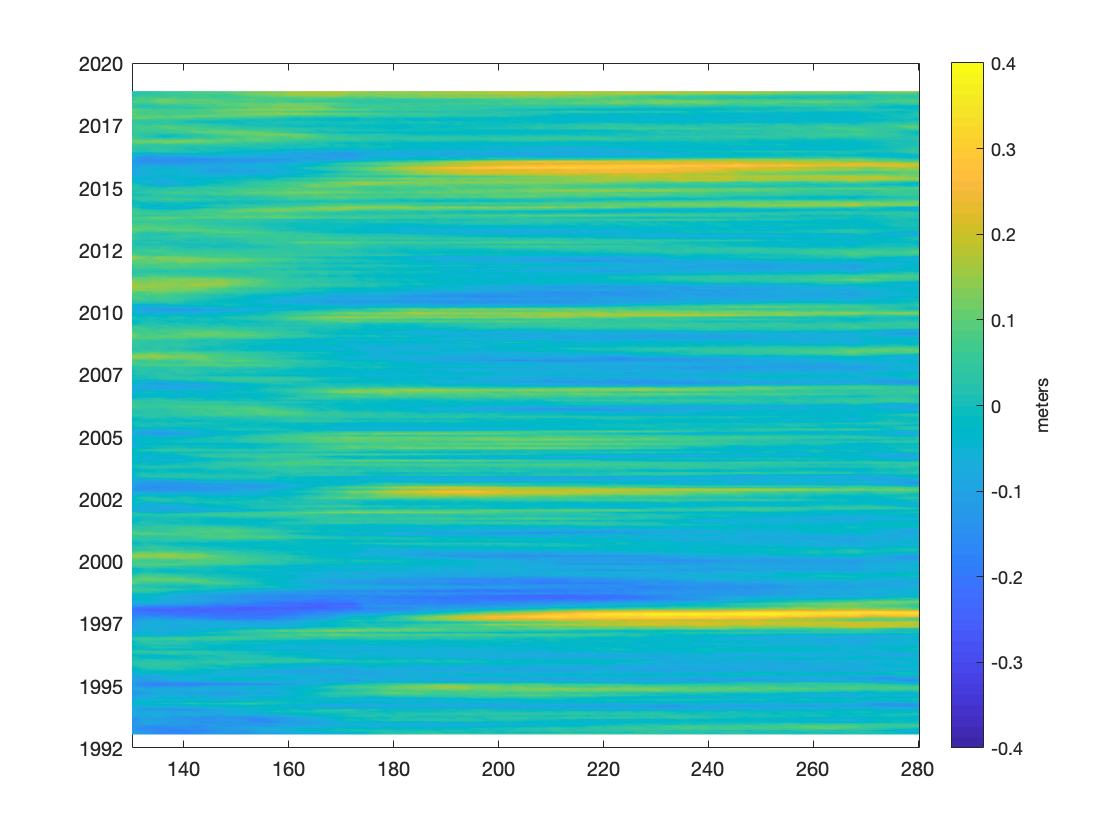

figure (1)
pcolor(lon,t,h)
shading interp
datetick('y')
cb = colorbar;
caxis([-.4 .4])
ylabel(cb,'meters')

**Plot a sea level animation**

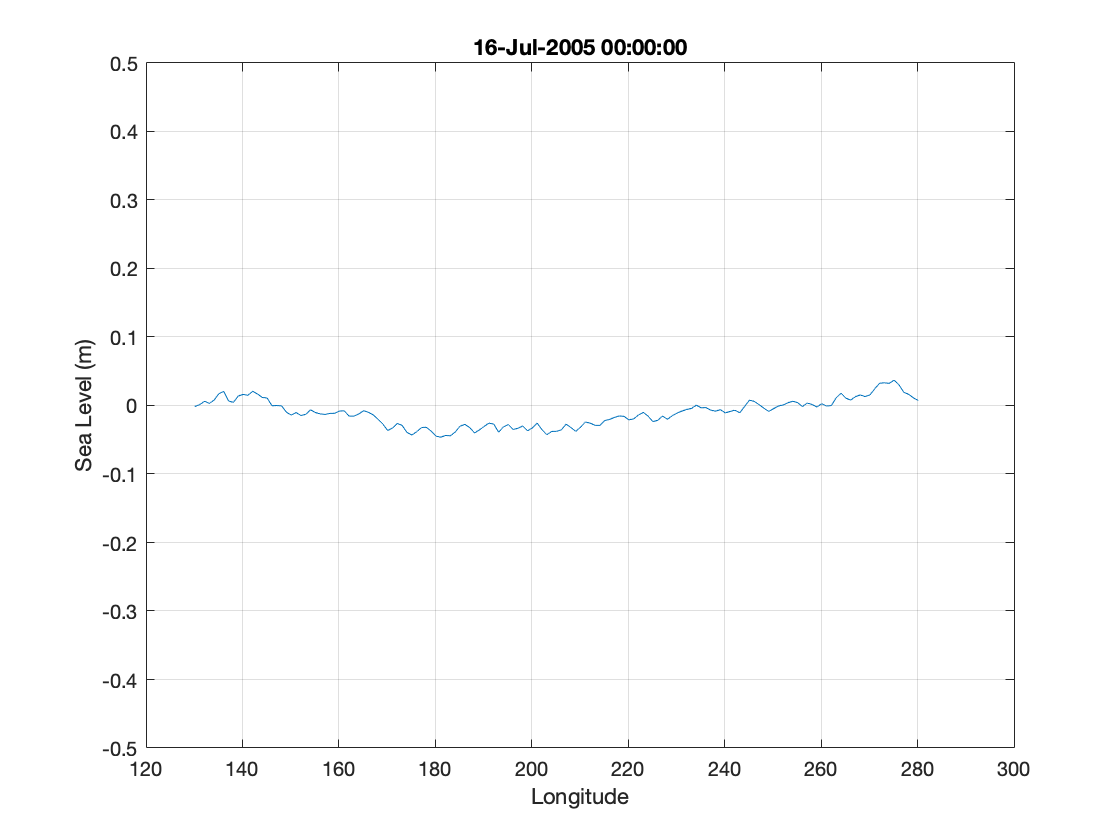

figure (2) % line plot
% plot sl as it changes across pacfic
tstr = datestr(datetime(t,'ConvertFrom','datenum'));

for i=1:151
    plot(lon,h(i,:))
    grid on
    xlabel('Longitude')
    ylabel('Sea Level (m)')
    ylim([-0.5 0.5])
    title([tstr(i,:)])
    pause(0.01)
end

Method 1: EOFs using covariance averaged in time

C = 1/(nt-1)*h'*h;          %covariance matrix
% h' * h  sums up the all covariances of all elements mult with eachother
% 1/(nt-1)*h' * h gives one over the variance 
% on diags C(i,i) variance of how h varies with itself, off-diags variance
% with other elements

[e,lambda] = eig(C);        %e = eigenvectors, lambda = eigenvalues
a = h*e;                   %a = temporal expansion == eigenvect times original data set (projecting?)

**Plot (imagesc) of the covariance matrix**

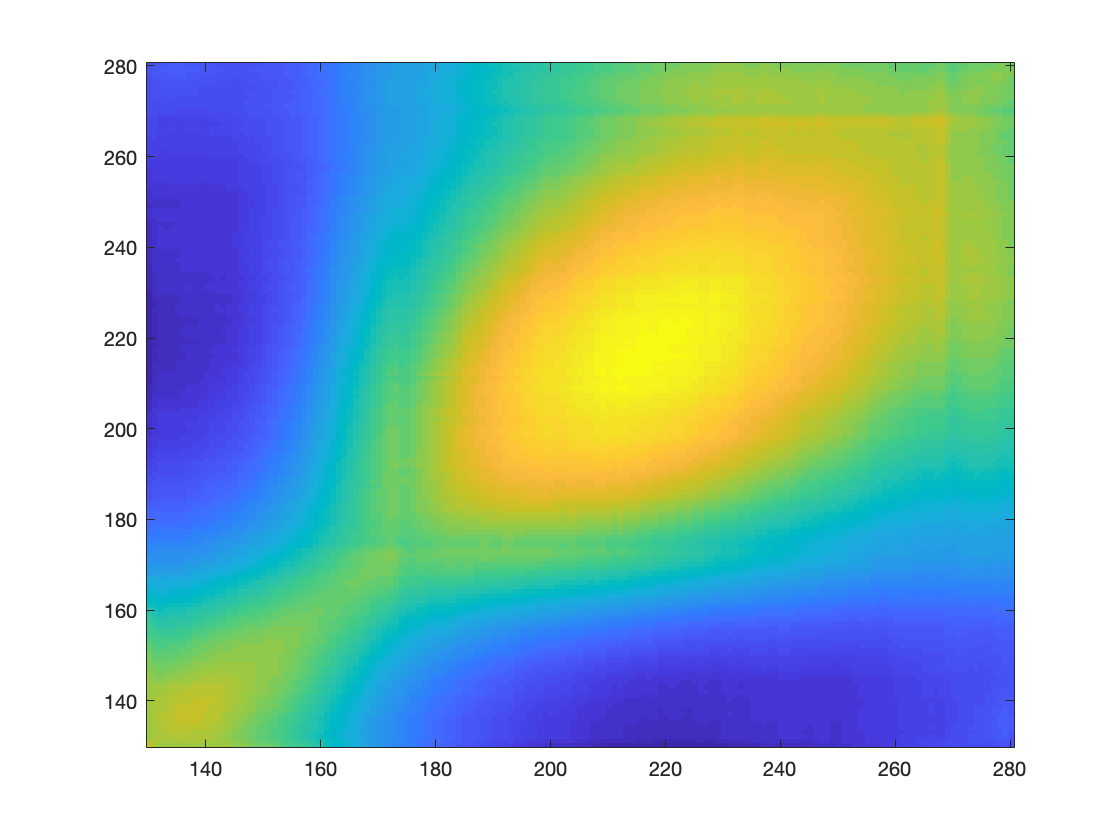

figure (3)
imagesc(lon,lon,C)
set(gca,'ydir','normal')

Plot percent variance explained by each mode

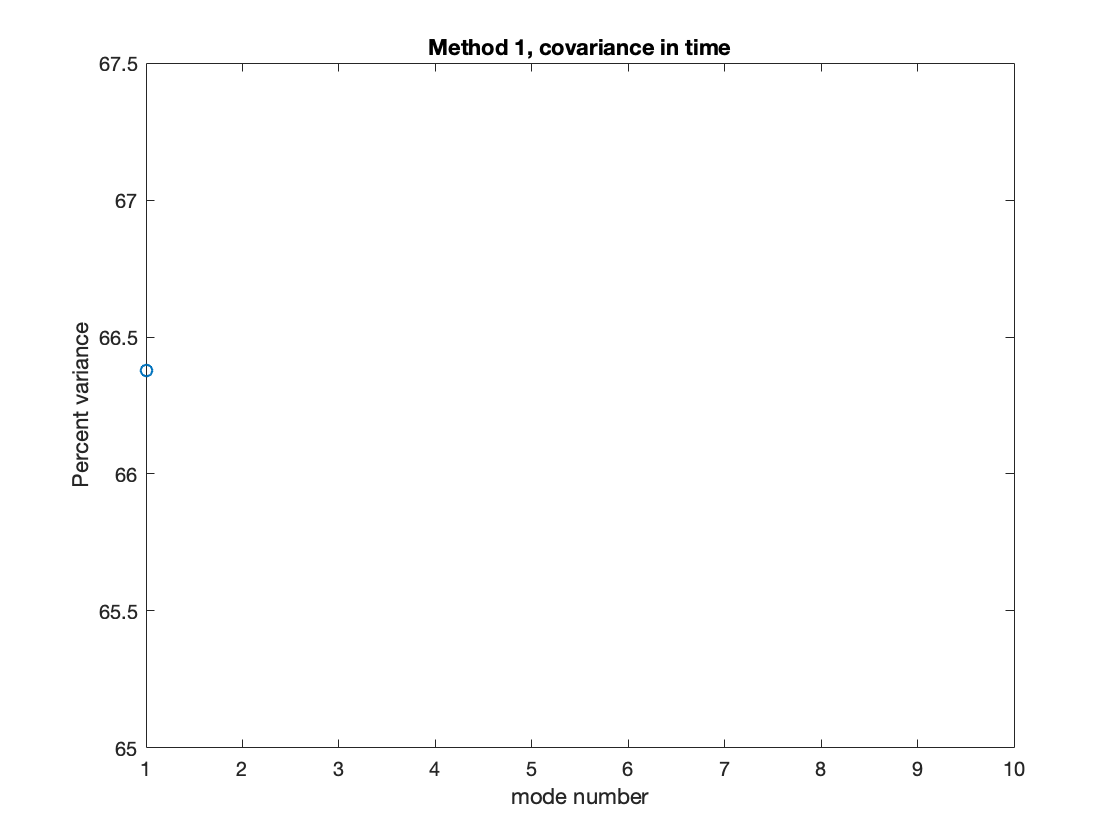

figure (4)
pvar = lambda(1)/sum(diag(lambda))*100; % total variance = sum(lambda(:)) == sum(diag(C))
plot(pvar,'o-') % percent variance
xlim([1,10])
ylabel('Percent variance')
xlabel('mode number')
title('Method 1, covariance in time')

Plot first 2 eigenvectors (EOFs)

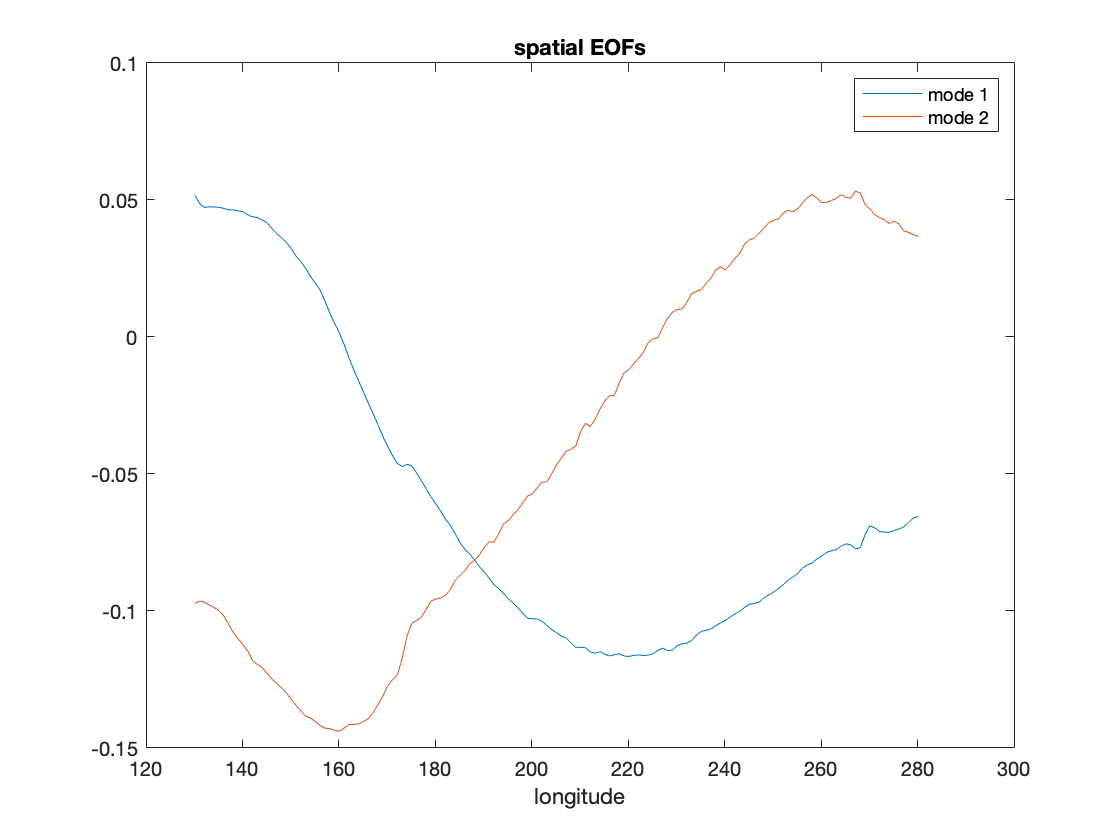

figure (5)
plot(lon,e(:,1:2))
legend('mode 1','mode 2')
xlabel('longitude')
title('spatial EOFs')

% 1/(nt-1)*sum(e(:,1).*e(:,2)) ~= 0 orthogonal functions should equal zero
% sum(pvar(1:2)) = .98 percent of variance within 2 modes
% sum(e(:,1).*e(:,1)) = 1 orthogonal i=j=1

Plot first 2 temporal expansions (PCs)

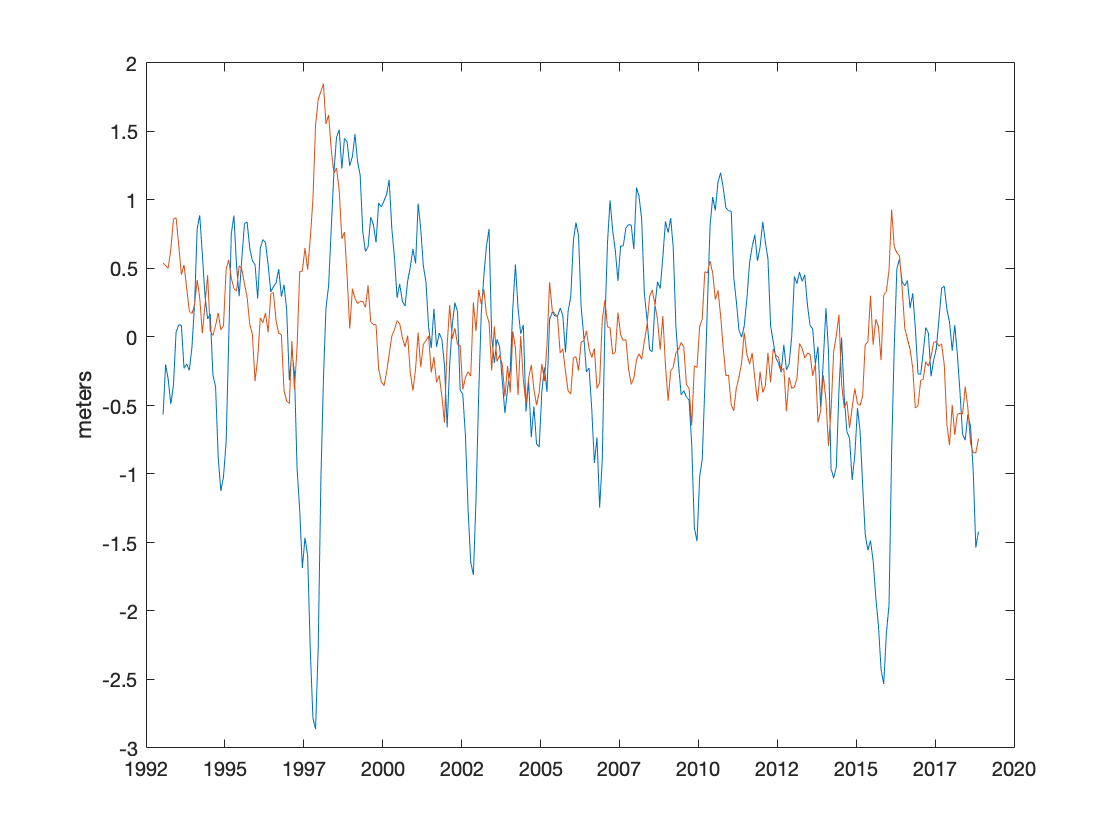

figure (6)
plot(t,a(:,1:2))
datetick
ylabel('meters')

**Plot time series at one point, overplot modes 1 and 2 at that point**

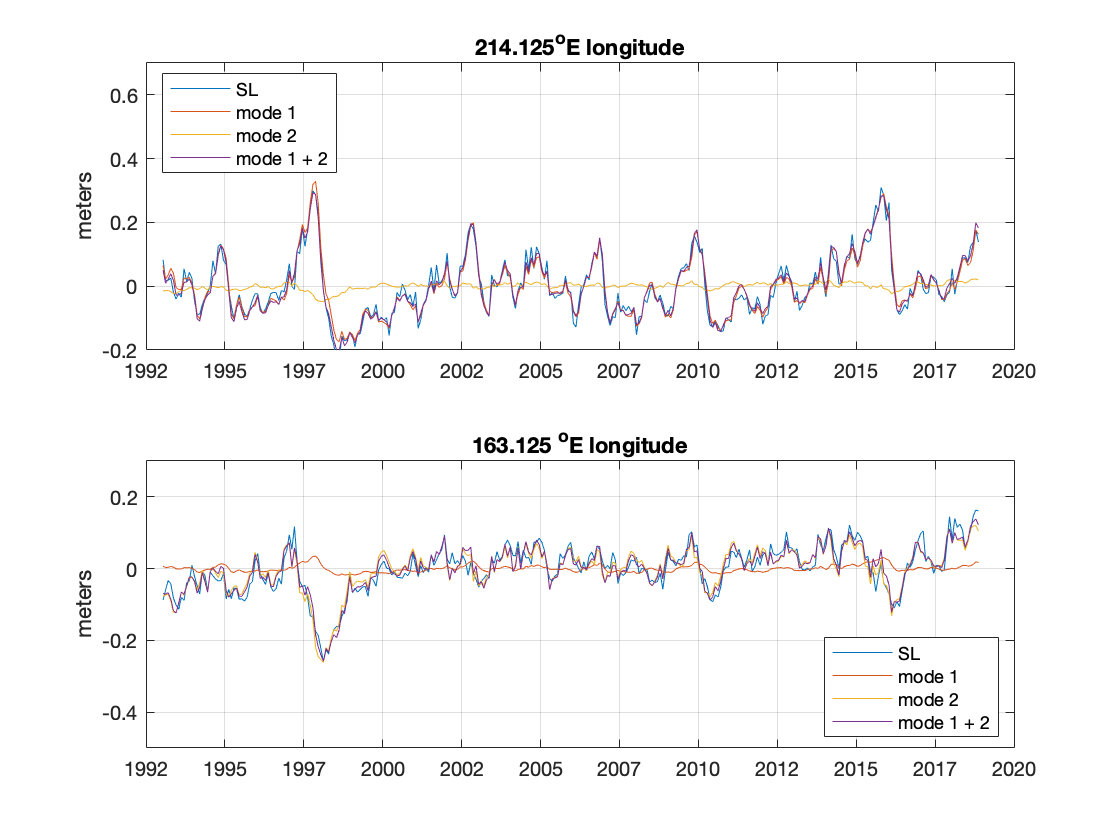

% reconstruct time series at one point 
% mode 1 and mode 2 should give most of the variability of the time series
% 85 longitude 
clf
figure (7) %pick lon 175
subplot(2,1,1)
plot(t,h(:,85),t,a(:,1)*e(85,1),t,a(:,2)*e(85,2),t,a(:,1)*e(85,1)+a(:,2)*e(85,2))
legend('SL','mode 1','mode 2','mode 1 + 2','location','NW')
ylabel('meters');datetick;ylim([-0.2 0.7]);grid
title([num2str(lon(85)) '^oE longitude'])
subplot(2,1,2)
plot(t,h(:,34),t,a(:,1)*e(34,1),t,a(:,2)*e(34,2),t,a(:,1)*e(34,1)+a(:,2)*e(34,2))
legend({'SL','mode 1','mode 2','mode 1 + 2'},'Location','SE')
ylabel('meters');datetick; ylim([-0.5 0.3]);grid
title([num2str(lon(34)) ' ^oE longitude'])

% lon(34) in west pacific? so we see more error  (variability?) from actual SL (blue line) 

**Redo the Hovmuller using only mode 1**

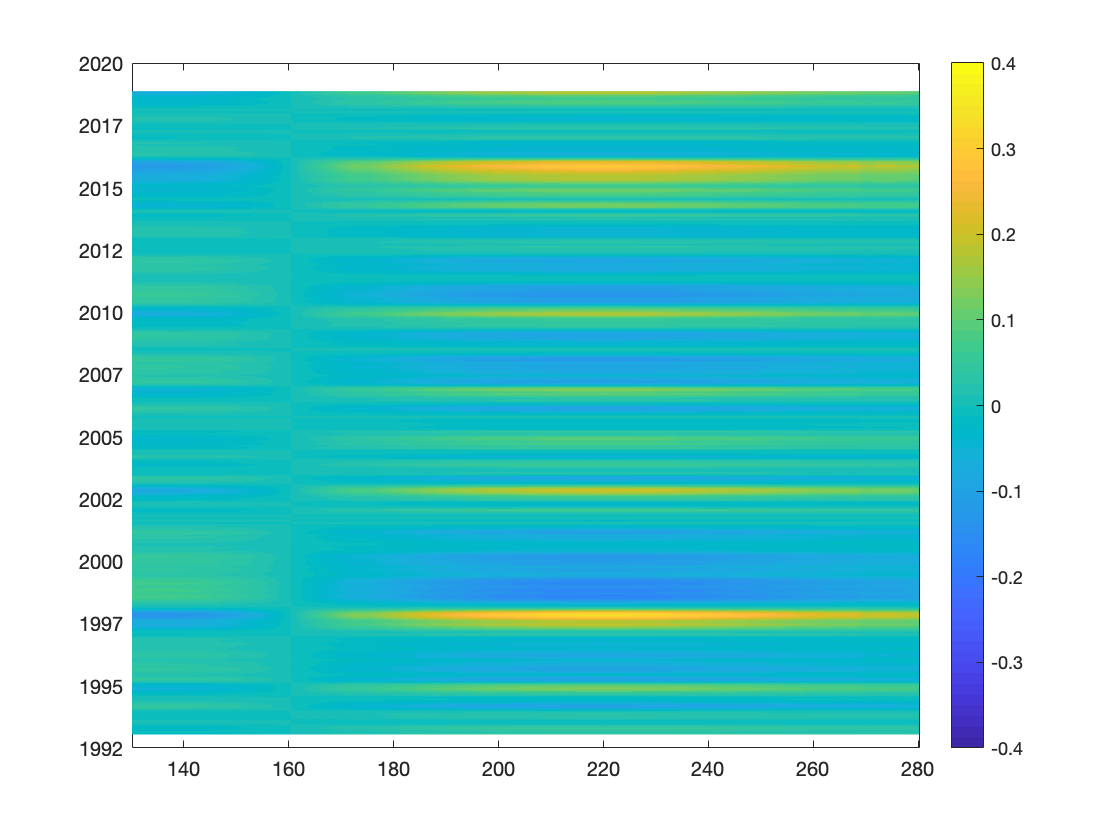

figure (8)
hm1 = a(:,1)*e(:,1)';
pcolor(lon,t,hm1)
shading interp
datetick('y')
colorbar
caxis([-0.4 0.4])

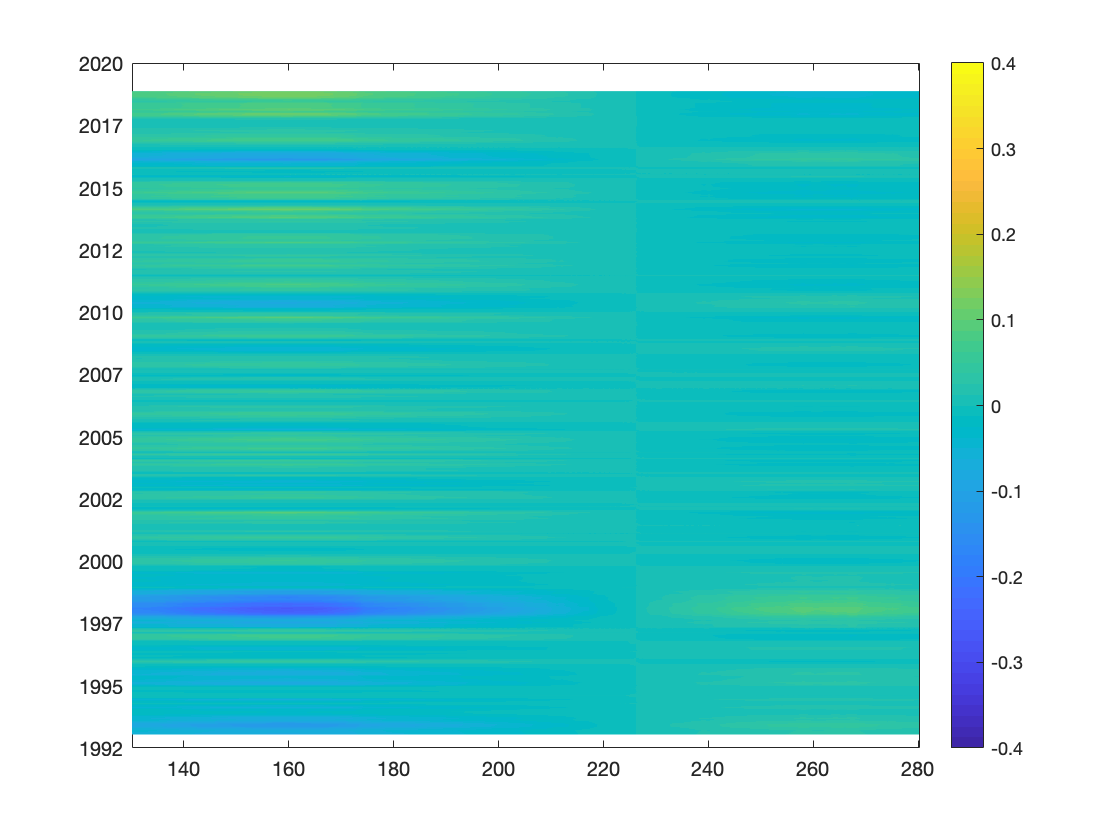

figure (9)
hm2 = a(:,2)*e(:,2)';
pcolor(lon,t,hm2)
shading interp
datetick('y')
colorbar
caxis([-0.4 0.4])

figure(10)
for j=1:nt
    plot(lon(h(j,:),'linewidth',2))
    ylim([-.5 .5])
    plot(lon,hm1(j,:)+hm2(j,:))
    ylim([-.5 .5])
    pause(.1)
end

Index in position 1 is invalid. Array indices must be positive integers or logical values.

%look at new code on website